# KUKA KR 10 R1100-2

Author ~ Ahmed Magd Aly

Innopolis University

## 1) Arm Part (q1, q2, q3):


$$\textrm{T123}=\textrm{Rz}\left(\textrm{q1}\right)*\textrm{Tx}\left(\textrm{d1}\right)\textrm{Ry}\left(\textrm{q2}\right)*\textrm{Tz}\left(\textrm{d2}\right)*\textrm{Ry}\left(\textrm{q3}+\Delta q\right)*\textrm{Tx}\left(\textrm{d3}\right)$$


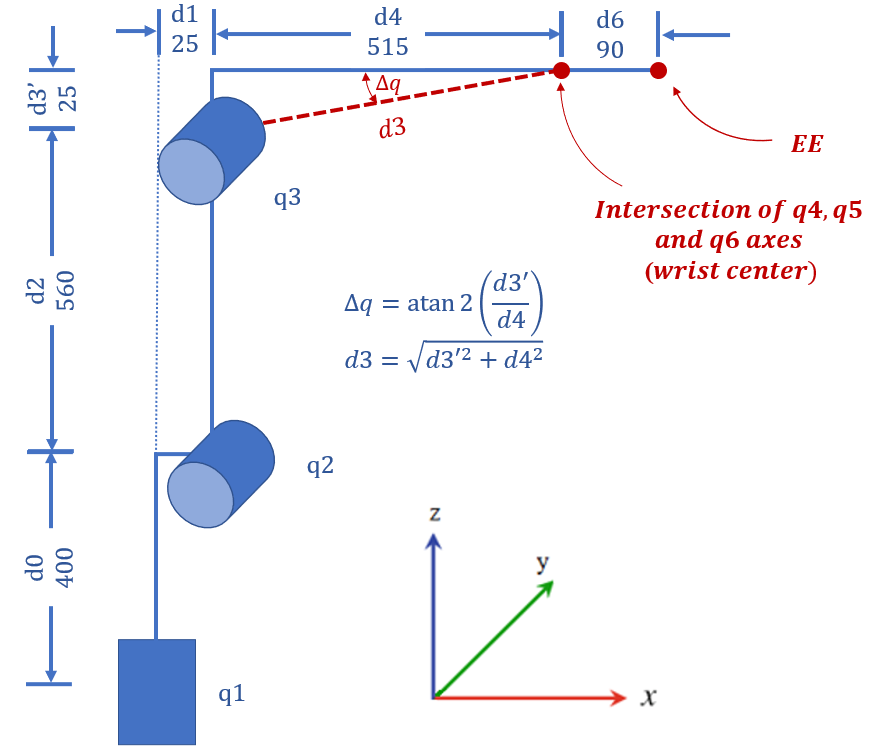

syms q1 q2 q3 q4 q5 q6 dq d1 d2 d3
T123 = Rz(q1)*Tx(d1)*Ry(q2)*Tz(d2)*Ry(q3+dq)*Tx(d3);
T123 = simplify(T123)

$$T123 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{3}\,\cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & \sigma_{1}\,\cos\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sigma_{2}\\ \sigma_{3}\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & \sigma_{1}\,\sin\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sigma_{2}\\ -\sigma_{1} & 0 & \sigma_{3} & d_{2}\,\cos\left(q_{2}\right)-d_{3}\,\sigma_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\mathrm{dq}+q_{2}+q_{3}\right)\\ \sigma_{2}=d_{1}+d_{2}\,\sin\left(q_{2}\right)+d_{3}\,\sigma_{3}\\ \sigma_{3}=\cos\left(\mathrm{dq}+q_{2}+q_{3}\right) \end{array}$$

### Compare T123 with T0, which has the same position vector:


$$\begin{array}{l}
\textrm{T0}={\textrm{Tz}}^{-1} \left(\textrm{d0}\right)*T*{\textrm{Tx}}^{-1} \left(\textrm{d6}\right)\\
\textrm{T0}=\left\lbrack \begin{array}{cc}
R & \left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack \\
0 & 1
\end{array}\right\rbrack \\
\textrm{where}\;T\;\textrm{is}\;\textrm{the}\;\textrm{tranformation}\;\textrm{matrix}\;\textrm{from}\;\textrm{the}\;\textrm{world}\;\textrm{frame}\;\textrm{to}\;\textrm{the}\;\textrm{end}-\textrm{effector}
\end{array}$$


### So we concluded that:


$$\begin{array}{l}
x=\cos \left(\textrm{q1}\right)*\left(\textrm{d1}+\textrm{d2}*\sin \left(\textrm{q2}\right)+\textrm{d3}*\cos \left(\textrm{dq}+\textrm{q2}+\textrm{q3}\right)\right)\\
y=\sin \left(\textrm{q1}\right)*\left(\textrm{d1}+\textrm{d2}*\sin \left(\textrm{q2}\right)+\textrm{d3}*\cos \left(\textrm{dq}+\textrm{q2}+\textrm{q3}\right)\right)\\
z=\textrm{d2}*\cos \left(\textrm{q2}\right)-\textrm{d3}*\sin \left(\textrm{dq}+\textrm{q2}+\textrm{q3}\right)
\end{array}$$


So we can now find q1 to be:


$$\begin{array}{l}
\textrm{if}\;x\;\&\;y=0\\
\textrm{q1}=\textrm{any}\;\textrm{value}\\
\textrm{else}\\
\textrm{q1}=\textrm{atan2}\left(y,x\right)
\end{array}$$


also q1 might have another solution as shown in the figure below:

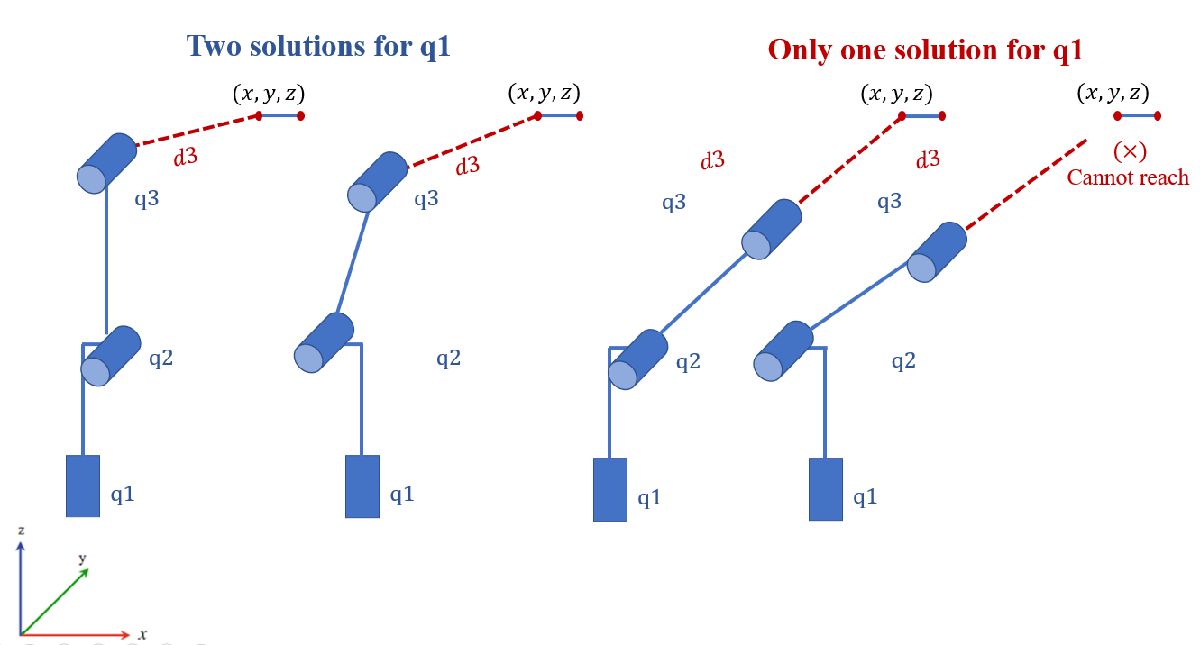

If it happened and q1 had another solution, then this solution will be (q1 + pi)

_____________

**Now for q2 and q3, let's consider the following figure**

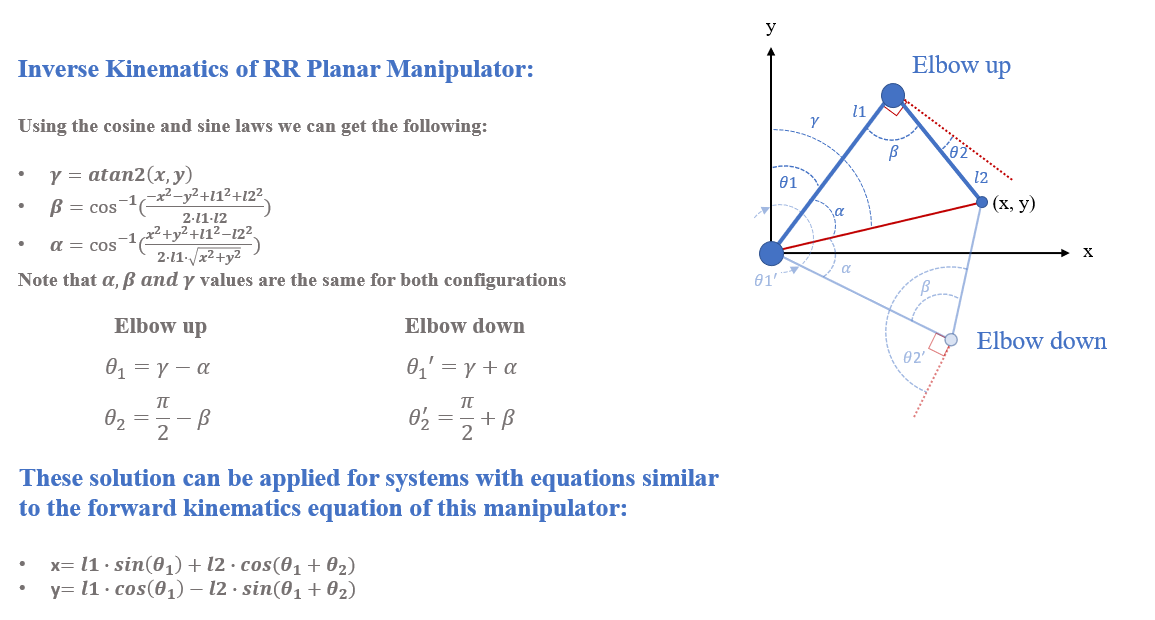

To convert the equations that we have got from T123 such that they can be applicable for the robot described above, we need the following:


$$\begin{array}{l}
\textrm{let}\;\textrm{X1}=\sqrt{x^2 +y^2 }-\textrm{d1}\\
\textrm{let}\;\textrm{X2}=-\sqrt{x^2 +y^2 }-\textrm{d1}\\
\textrm{let}\;Y=z
\end{array}$$



$$\begin{array}{l}
\pm X=\textrm{d2}*\cos \left(\textrm{q2}\right)+\textrm{d3}*\cos \left(\textrm{dq}+\textrm{q2}+\textrm{q3}\right)\\
Y=\pm X=\textrm{d2}*\cos \left(\textrm{q2}\right)+\textrm{d3}*\cos \left(\textrm{dq}+\textrm{q2}+\textrm{q3}\right)
\end{array}$$


By comparing these two equations with the planar RR manipulator, we get:


$$\begin{array}{l}
{\textrm{q3}}_1 =\pm \;\arccos \left(\frac{{\textrm{X1}}^2 +Y^2 -{\textrm{d2}}^2 -{\textrm{d3}}^2 }{2*\textrm{d2}*\textrm{d3}}\right)\\
{\textrm{q3}}_2 =\pm \;\arccos \left(\frac{{\textrm{X2}}^2 +Y^2 -{\textrm{d2}}^2 -{\textrm{d3}}^2 }{2*\textrm{d2}*\textrm{d3}}\right)\\
\textrm{if}\;\textrm{q3}>0\\
\textrm{q2}=\textrm{atan}\left(\frac{\textrm{d3}*\cos \left(\textrm{q3}\right)}{\textrm{d2}+\textrm{d3}*\sin \left(\textrm{q3}\right)}\right)+\textrm{atan}\left(\frac{Y}{X}\right)\\
\textrm{else}\\
\textrm{q2}=-\textrm{atan}\left(\frac{\textrm{d3}*\cos \left(\textrm{q3}\right)}{\textrm{d2}+\textrm{d3}*\sin \left(\textrm{q3}\right)}\right)+\textrm{atan}\left(\frac{Y}{X}\right)
\end{array}$$


## 2) Wrist Part (q4, q5, q6):

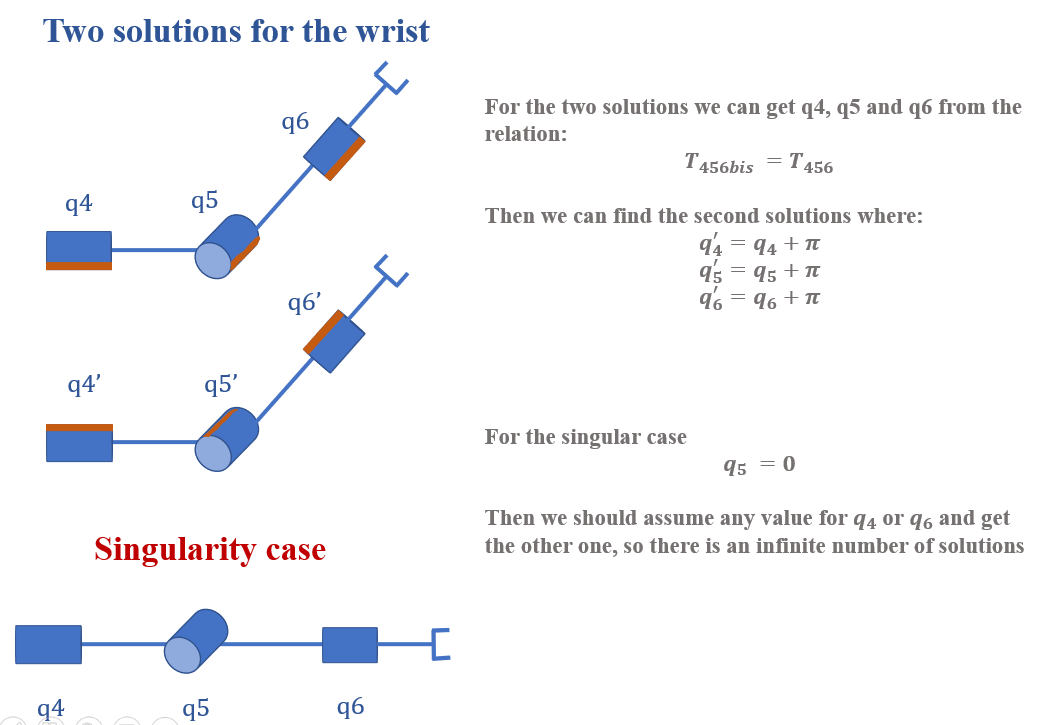

T456 = Rx(q4)*Ry(q5)*Rx(q6);
T456 = simplify(T456)

$$T456 = \left(\begin{array}{cccc} \cos\left(q_{5}\right) & \sin\left(q_{5}\right)\,\sin\left(q_{6}\right) & \cos\left(q_{6}\right)\,\sin\left(q_{5}\right) & 0\\ \sin\left(q_{4}\right)\,\sin\left(q_{5}\right) & \cos\left(q_{4}\right)\,\cos\left(q_{6}\right)-\cos\left(q_{5}\right)\,\sin\left(q_{4}\right)\,\sin\left(q_{6}\right) & -\cos\left(q_{4}\right)\,\sin\left(q_{6}\right)-\cos\left(q_{5}\right)\,\cos\left(q_{6}\right)\,\sin\left(q_{4}\right) & 0\\ -\cos\left(q_{4}\right)\,\sin\left(q_{5}\right) & \cos\left(q_{6}\right)\,\sin\left(q_{4}\right)+\cos\left(q_{4}\right)\,\cos\left(q_{5}\right)\,\sin\left(q_{6}\right) & \cos\left(q_{4}\right)\,\cos\left(q_{5}\right)\,\cos\left(q_{6}\right)-\sin\left(q_{4}\right)\,\sin\left(q_{6}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


$$\left\lbrack \begin{array}{cccc}
\textrm{m11} & \textrm{m12} & \textrm{m13} & 0\\
\textrm{m21} & \textrm{m22} & \textrm{m23} & 0\\
\textrm{m31} & \textrm{m32} & \textrm{m33} & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


From these equations we get that:


$$\begin{array}{l}
\textrm{if}\;\left|\textrm{m11}\right|~=1\\
\textrm{q4}=\textrm{atan2}\left(\textrm{m21},-\textrm{m31}\right)\\
\textrm{q6}=\textrm{atan2}\left(\textrm{m12},\textrm{m13}\right)\\
\textrm{q5}=\textrm{atan2}\left(\sqrt{{\textrm{m21}}^2 +{\textrm{m31}}^2 },\textrm{m11}\right)\;\textrm{or}\;\;\textrm{atan2}\left(\sqrt{{\textrm{m12}}^2 +{\textrm{m13}}^2 },\textrm{m11}\right)\\
\textrm{else}\\
\textrm{q5}=0\;\textrm{and}\;\textrm{we}\;\textrm{have}\;\textrm{to}\;\textrm{assume}\;\textrm{either}\;\textrm{q4}\;\textrm{or}\;\textrm{q6}\;\textrm{and}\;\textrm{get}\;\textrm{the}\;\textrm{other}\;\textrm{one}\;
\end{array}$$


So in the singulairty case the matrix will be as follow:

T456 = subs(T456, q5, 0)

$$T456 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \cos\left(q_{4}\right)\,\cos\left(q_{6}\right)-\sin\left(q_{4}\right)\,\sin\left(q_{6}\right) & -\cos\left(q_{4}\right)\,\sin\left(q_{6}\right)-\cos\left(q_{6}\right)\,\sin\left(q_{4}\right) & 0\\ 0 & \cos\left(q_{4}\right)\,\sin\left(q_{6}\right)+\cos\left(q_{6}\right)\,\sin\left(q_{4}\right) & \cos\left(q_{4}\right)\,\cos\left(q_{6}\right)-\sin\left(q_{4}\right)\,\sin\left(q_{6}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

If would assume q4 to always be 0 in singulairty cases we get:

T456 = subs(T456, q4, 0)

$$T456 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \cos\left(q_{6}\right) & -\sin\left(q_{6}\right) & 0\\ 0 & \sin\left(q_{6}\right) & \cos\left(q_{6}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

So in this case we get


$$\textrm{q6}=\textrm{atan}\left(\textrm{m32},\textrm{m22}\right)$$
